Q1 - Function 1 using the normal equations method

format long
% initialize variables for all the functions
syms f1(t) f2(t) f3(t) f4(x)

% import the data
data = importdata('Ass_2_Q1_data.txt');

lenData = length(data);
A1 = ones(lenData, 3);
B1 = zeros(lenData, 1);

% create the desired matrices 
for i=1:lenData
    A1(i,2) = data(i,1);
    A1(i,3) = data(i,1)^2;
    B1(i) = data(i,2);
end

A_T1 = transpose(A1);
sqr1 = A_T1*A1;
ATB1 = A_T1*B1;
% calculate the upper and lower triangle using cholosky
L1 = chol(sqr1, 'lower');
L_T1 = chol(sqr1, 'upper');

z1 = inv(L1)*ATB1;
x1 = inv(L_T1)*z1;
x1 = transpose(x1)

x1 =    0.250922262575244  -0.111345919449174   0.009651643345421


% compare with the using the equation
x1 = inv(sqr1)*ATB1;
x1 = transpose(x1)

x1 =    0.250922262575244  -0.111345919449175   0.009651643345421


% show the final function
f1(t) = x1(1) + x1(2)*t + x1(3)*t^2;

% calculate the Standard Error
Sr = sum((B1 - A1*transpose(x1)).^2);
syx = sqrt(Sr/(lenData - length(x1)))

syx =    0.254121724190224


Function 2 - 

A2 = ones(lenData-1, 2);
B2 = zeros(lenData-1, 1);

for i=2:lenData
    A2(i-1, 2) = log(data(i,1));
    
    B2(i-1) = log(data(i,2)+10);
end

% calculate using normal equations method
A_T2 = transpose(A2);
sqr2 = A_T2*A2;
ATB2 = A_T2*B2;
% calculate the upper and lower triangle using cholosky
L2 = chol(sqr2, 'lower');
L_T2 = chol(sqr2, 'upper');

z2 = inv(L2)*ATB2;
x2 = inv(L_T2)*z2;
x_comp = x2

x_comp =    2.315114302804514
  -0.009034108441029


x2 = real(transpose(x2))

x2 =    2.315114302804514  -0.009034108441029


% compare with the using the equation
%x2 = inv(sqr2)*ATB2
%x2 = real(transpose(x2))
f2(t) = exp(x2(1))*t^(x2(2))-10

$$f2(t) = \frac{5700476428706467}{562949953421312\,t^{5207808948306447/576460752303423488}}-10$$

% calculate the Standard Error
Sr = abs(real(sum((B2 - A2*x_comp).^2)))

Sr =    0.052413599705553


syx = sqrt(Sr/(lenData-1 - length(x_comp)))

syx =    0.023126449145009


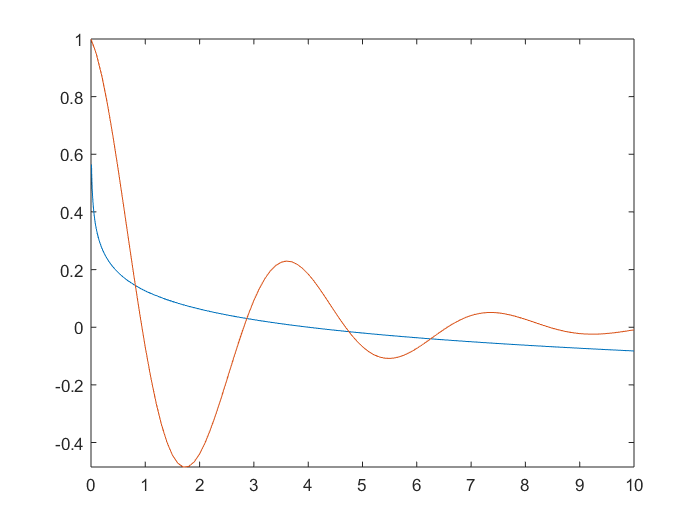

fplot(f2(t), [0,10])
hold on
plot(data(:,1), data(:,2))
hold off

Function 3 

A3 = zeros(lenData-1, 2);
B3 = zeros(lenData-1, 1);

for i=2:lenData
    A3(i, 1) = 1;
    A3(i, 2) = data(i,1);
    
    B3(i) = 1/data(i,2);
end

% calculate using normal equations method
A_T3 = transpose(A3);
sqr3 = A_T3*A3;
ATB3 = A_T3*B3;

% calculate the upper and lower triangle using cholosky
L3 = chol(sqr3, 'lower');
L_T3 = chol(sqr3, 'upper');

z3 = inv(L3)*ATB3;
x3 = inv(L_T3)*z3;
x3 = transpose(x3)

x3 =    2.460584788079077  -1.753352823972599


% compare with the using the equation
x3 = inv(sqr3)*ATB3;
x3 = transpose(x3)

x3 =    2.460584788079075  -1.753352823972598



f3(t) = 1/(x3(1) + x3(2)*t)

$$f3(t) = -\frac{1}{\frac{246762472646625\,t}{140737488355328}-\frac{43287065369947}{17592186044416}}$$

% calculate the Standard Error
Sr = sum((B3 - A3*transpose(x3)).^2);
syx = sqrt(Sr/(lenData - length(x3)))

syx =   76.753837532477405


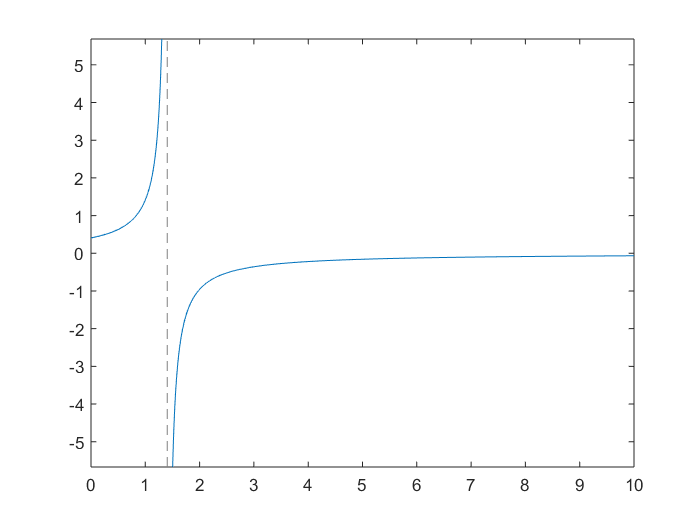

fplot(f3(t), [0,10])
hold off

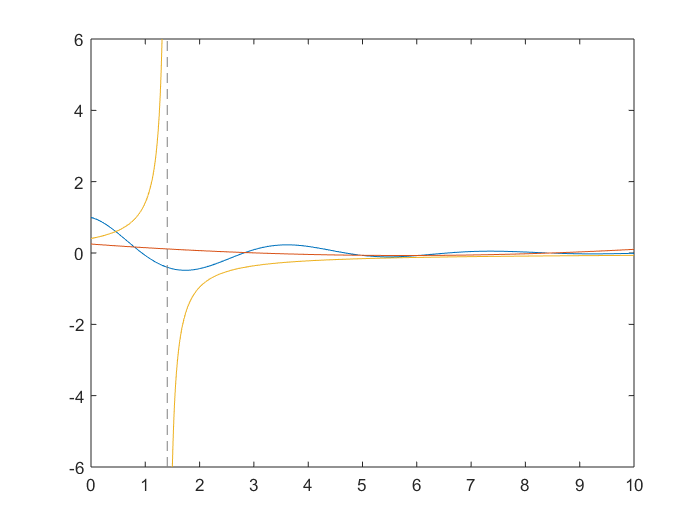


plot(data(:,1), data(:,2))
hold on
fplot(f1(t), [0,10])
hold on 
fplot(f3(t), [0,10])
hold off